# **Hough Transforms**

## Part 1: Hough Lines --------------------------------------------------------------------------------------------

## Import Lines Photo and Acquire Dimensions

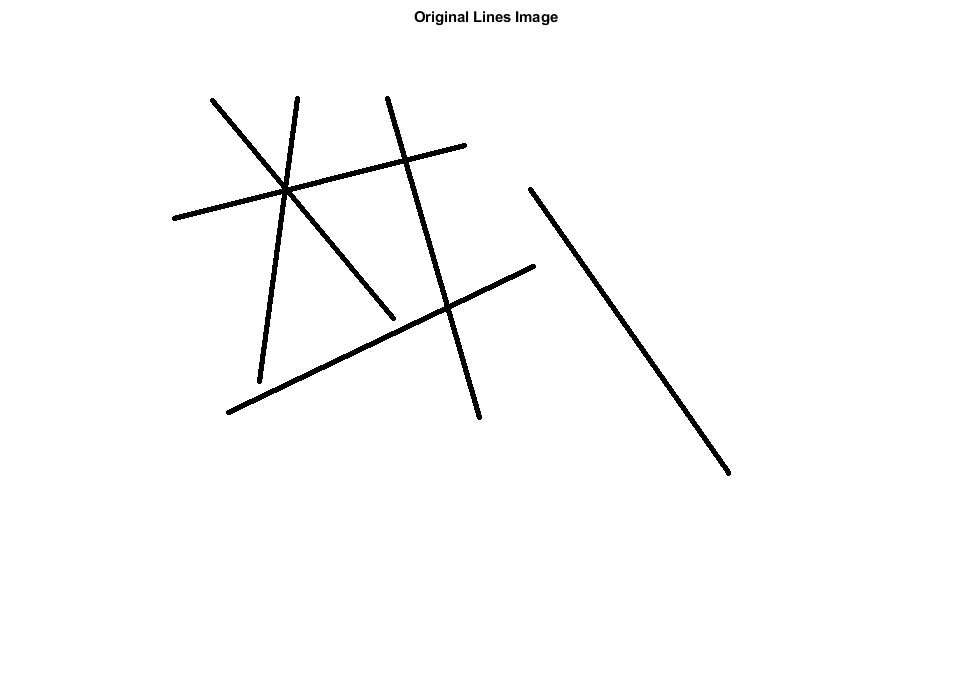

lines = rgb2gray(imread('line1.jpg'));
[H, W] = size(lines);
figure
imshow(lines);
title("Original Lines Image");

## Perform Edge Detection and Thresholding on Lines

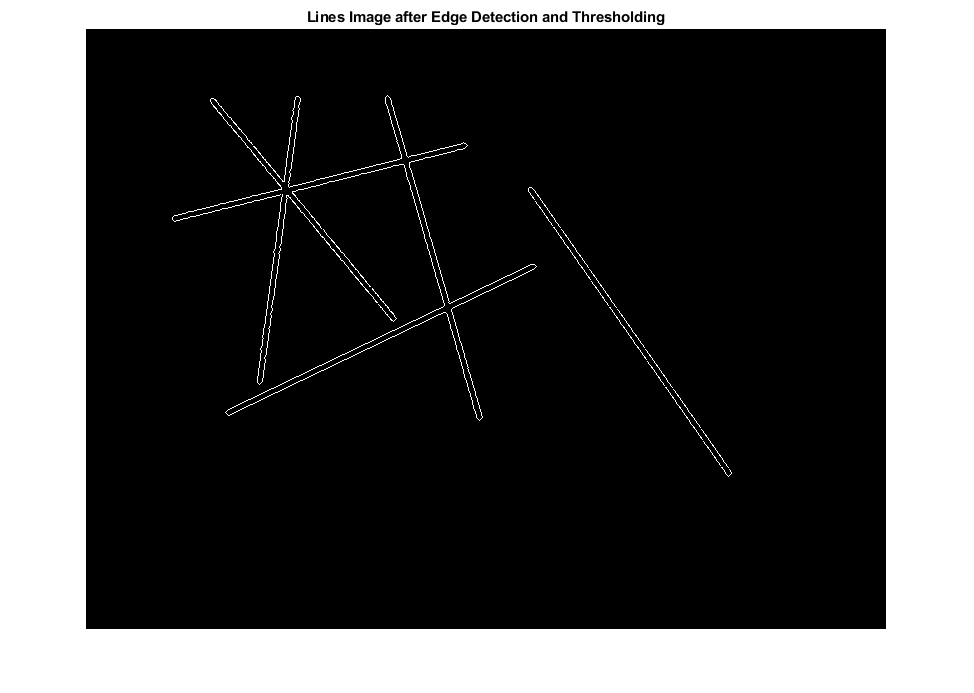

edgeLines = edge(lines);
threshold = graythresh(uint8(edgeLines));
threshLines = (edgeLines > threshold);
figure
imshow(threshLines);
title("Lines Image after Edge Detection and Thresholding");

## Find Accumulator Array using Hough Transform

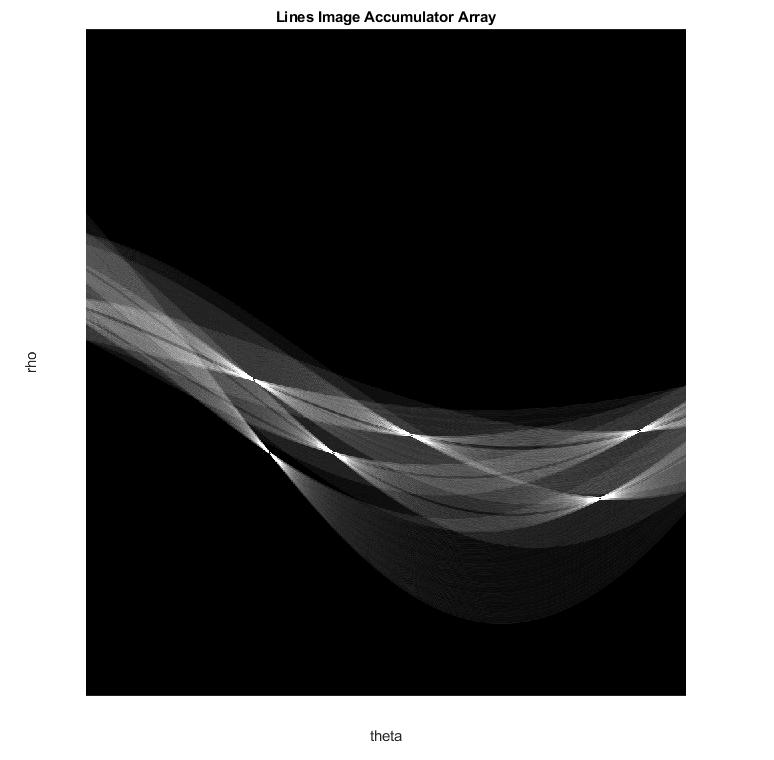

[y, x] = find(threshLines); % x and y indicies of each white pixel (edges).
y = single(y); x = single(x);N = length(y);
imgDiag = sqrt(H^2 + W^2);
rhos = linspace(-imgDiag, imgDiag, imgDiag)';
thetas = (-90:0.2:89.8)';
Accumulator = zeros(length(rhos), length(thetas));

for i = 1:N
    for j = 1:length(thetas)
        rho = x(i) * cos(deg2rad(thetas(j))) + y(i) * sin(deg2rad(thetas(j)));
        if (rho >= -imgDiag && rho < imgDiag) % if this is a valid rho value:
            [~, ix] = min(abs(rhos - rho)); % find index of val in rhos that is closest to rho.
            Accumulator(ix, j) = Accumulator(ix, j) + 1; % vote for this rho-theta combination.
        end
    end
end

% Display the Accumulator Array
showAccum(Accumulator);

## Determine the Rho-Theta Pairs for the 6 Lines

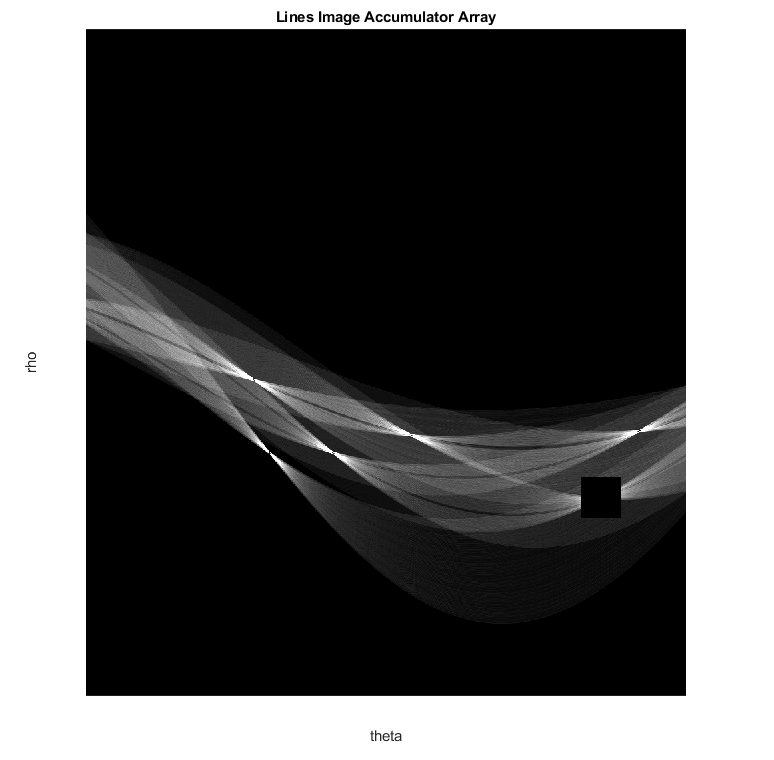

A = Accumulator;

% Max 1:
[~, idx] = max(A(:));
[rho, theta] = ind2sub(size(A),idx);
A = maskAccum_lines(A, rho, theta);
showAccum(A);

fprintf("Line 1\n\trho: %f\n\ttheta: %f\n", rhos(rho), thetas(theta));

Line 1
	rho: 405.405405
	theta: 64.400000


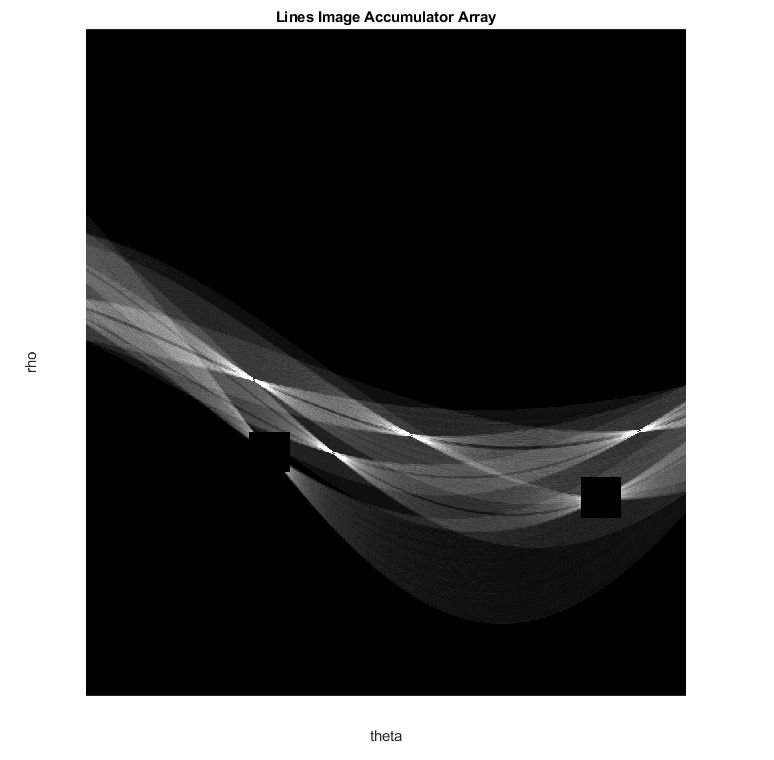


% Max 2:
[~, idx] = max(A(:));
[rho, theta] = ind2sub(size(A),idx);
A = maskAccum_lines(A, rho, theta);
showAccum(A);

fprintf("Line 2\n\trho: %f\n\ttheta: %f\n", rhos(rho), thetas(theta));

Line 2
	rho: 269.269269
	theta: -35.000000


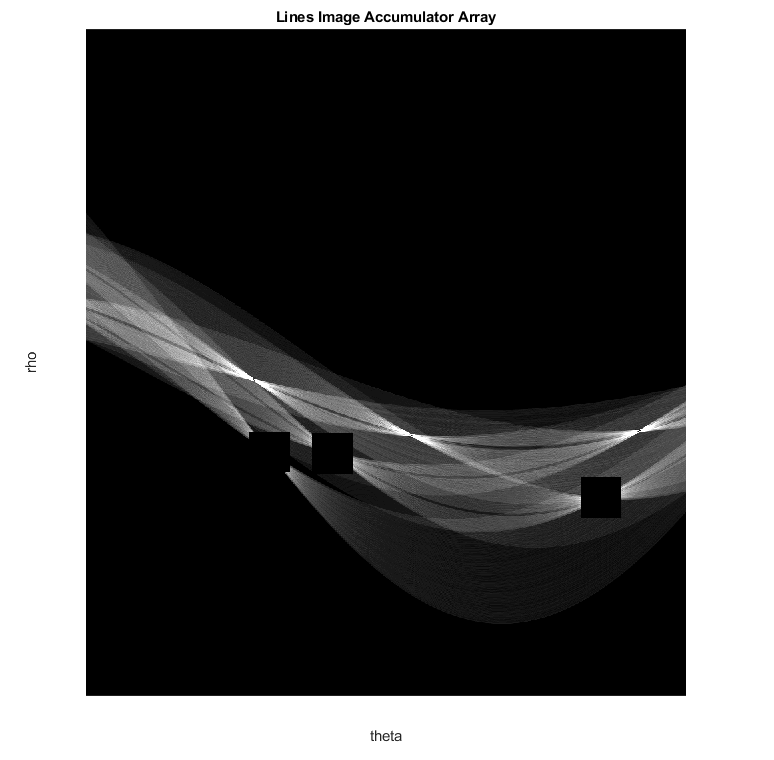


% Max 3:
[~, idx] = max(A(:));
[rho, theta] = ind2sub(size(A),idx);
A = maskAccum_lines(A, rho, theta);
showAccum(A);

fprintf("Line 3\n\trho: %f\n\ttheta: %f\n", rhos(rho), thetas(theta));

Line 3
	rho: 273.273273
	theta: -16.200000


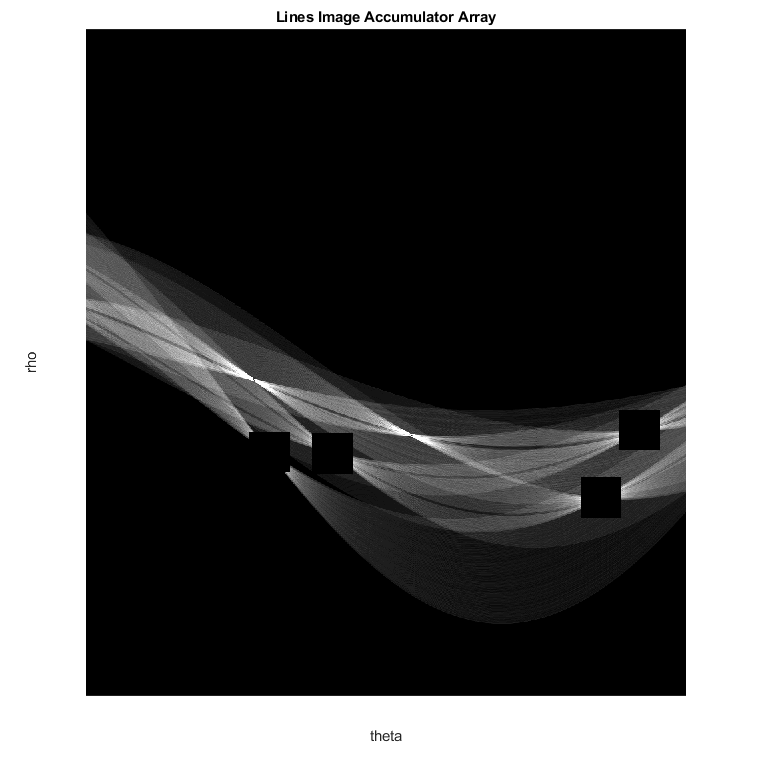


% Max 4:
[~, idx] = max(A(:));
[rho, theta] = ind2sub(size(A),idx);
A = maskAccum_lines(A, rho, theta);
showAccum(A);

fprintf("Line 4\n\trho: %f\n\ttheta: %f\n", rhos(rho), thetas(theta));

Line 4
	rho: 203.203203
	theta: 76.000000


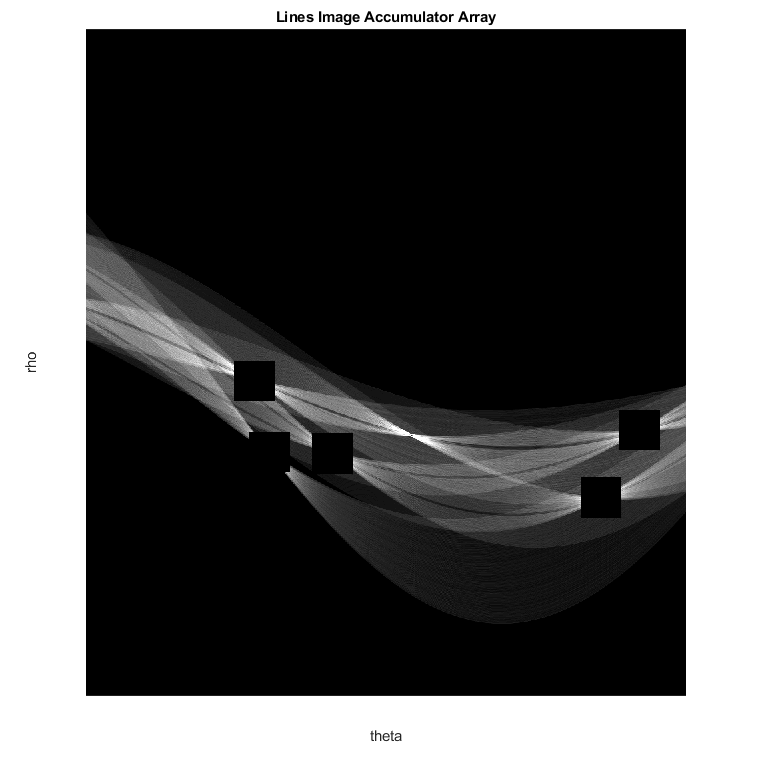


% Max 5:
[~, idx] = max(A(:));
[rho, theta] = ind2sub(size(A),idx);
A = maskAccum_lines(A, rho, theta);
showAccum(A);

fprintf("Line 5\n\trho: %f\n\ttheta: %f\n", rhos(rho), thetas(theta));

Line 5
	rho: 55.055055
	theta: -39.600000


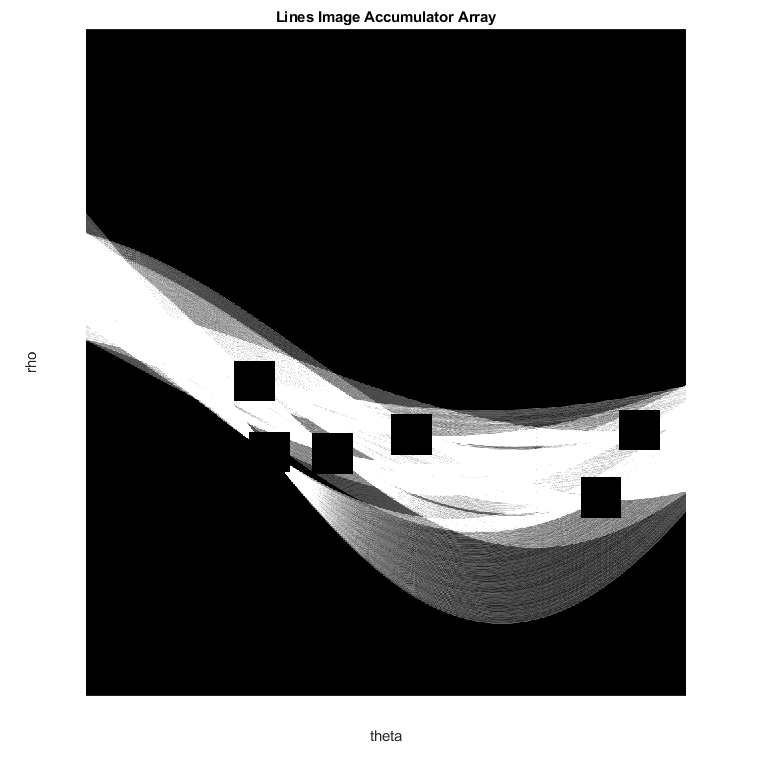


% Max 6:
[~, idx] = max(A(:));
[rho, theta] = ind2sub(size(A),idx);
A = maskAccum_lines(A, rho, theta);
showAccum(A);

fprintf("Line 6\n\trho: %f\n\ttheta: %f\n", rhos(rho), thetas(theta));

Line 6
	rho: 217.217217
	theta: 7.600000


This latest display image of the accumulator matrix is a bit saturated because I was using a simple multiplication on the accumulator matrix to enhance the visibility of the lines. The original matrix never changed values, it is just that without any higher valued points the display matrix from mat2gray() has given lower values a larger weight.

## Part 2: Hough Ellipses ----------------------------------------------------------------------------------------

## Import Ellipse Photo and Acquire Dimensions

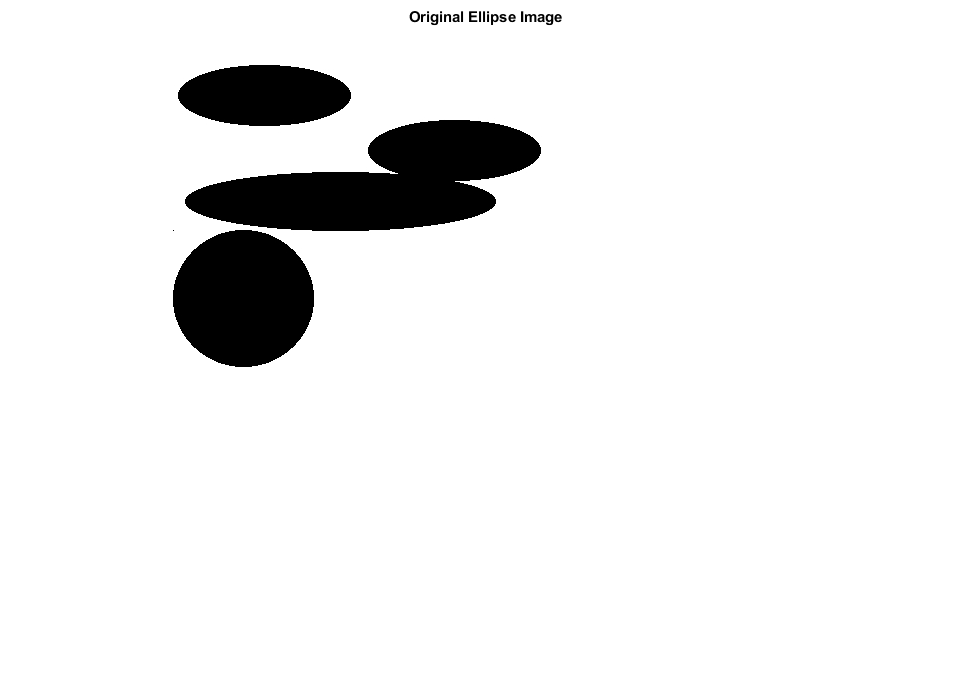

ellipses = rgb2gray(imread('ellipse1.jpg'));
[H, W] = size(ellipses);
figure
imshow(ellipses);
title("Original Ellipse Image");

## Perform Edge Detection and Thresholding on Ellispes

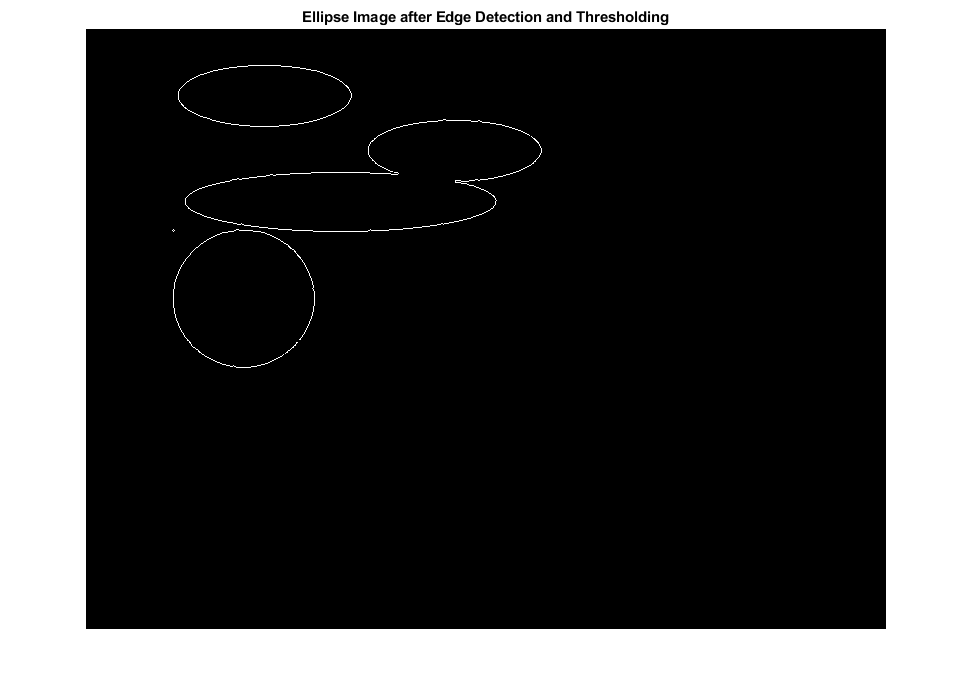

edgeEllipses = edge(ellipses);
threshold = graythresh(uint8(edgeEllipses));
threshEllipses = (edgeEllipses > threshold);
figure
imshow(threshEllipses);
title("Ellipse Image after Edge Detection and Thresholding");

## Find Image Gradient Direction Matrix

[Gx,Gy] = imgradientxy(ellipses);
thetas = atan2(Gy,Gx);

## Generate Accumulator Array using Hough Transform

[y, x] = find(threshEllipses); % x and y indicies of each white pixel (edges).
y = single(y); x = single(x);N = length(y);
alphas = (1:4:W/2)';
betas = (1:4:H/2)';
X0s = (1:4:W/2)';
Y0s = (1:4:H/2)';
Accumulator = zeros(length(alphas), length(betas), length(X0s), length(Y0s), 'uint16');

tic;
for i = 1:N
    for a = 1:length(alphas)
        for b = 1:length(betas)
            aa = alphas(a);
            bb = betas(b);
            th = thetas(y(i), x(i));
            
            if (aa >= bb) % this ensures that the x axis is the major axis of the ellipse.
                
                % compute possible X0 and Y0 values given the current (x,y,alpha,beta)
                x0_1 = x(i) + aa / sqrt(1 + (bb^2)/(aa^2 * tan(th)^2));
                x0_2 = x(i) - aa / sqrt(1 + (bb^2)/(aa^2 * tan(th)^2));
                
                y0_1 = y(i) + bb / sqrt(1 + (aa^2 * tan(th)^2)/(bb^2));
                y0_2 = y(i) - bb / sqrt(1 + (aa^2 * tan(th)^2)/(bb^2));
                
                % check if these X0 and Y0 values lie within the correct range of possible values:
                if (x0_1 >= 1 && x0_1 <= W/2) % if this is a valid X0 value:
                    [~, x0_1_ind] = min(abs(X0s - x0_1)); % find index of val in X0s that is closest to x0_1.
                else
                    x0_1_ind = false;
                end
                
                if (x0_2 >= 1 && x0_2 <= W/2) % if this is a valid X0 value:
                    [~, x0_2_ind] = min(abs(X0s - x0_2)); % find index of val in X0s that is closest to x0_2.
                else
                    x0_2_ind = false;
                end
                
                if (y0_1 >= 1 && y0_1 <= H/2) % if this is a valid Y0 value:
                    [~, y0_1_ind] = min(abs(Y0s - y0_1)); % find index of val in Y0s that is closest to y0_1.
                else
                    y0_1_ind = false;
                end
                
                if (y0_2 >= 1 && y0_2 <= H/2) % if this is a valid Y0 value:
                    [~, y0_2_ind] = min(abs(Y0s - y0_2)); % find index of val in Y0s that is closest to y0_2.
                else
                    y0_2_ind = false;
                end
                
                % now we can increment the accumulator parameter space values.
                if(x0_1_ind ~= false && y0_1_ind ~= false)
                    Accumulator(a,b,x0_1_ind,y0_1_ind) = Accumulator(a,b,x0_1_ind,y0_1_ind) + 1;
                end
                if(x0_2_ind ~= false && y0_2_ind ~= false)
                    Accumulator(a,b,x0_2_ind,y0_2_ind) = Accumulator(a,b,x0_2_ind,y0_2_ind) + 1;
                end
            end
        end
    end
    
end
toc;

Elapsed time is 362.333836 seconds.


## Determine the Rho-Theta Pairs for the 6 Lines

A = Accumulator;

% Max 1:
[~,idx] = max(A(:));
[alpha, beta, x0, y0] = ind2sub(size(A),idx);
A = maskAccum_ellipses(A, alpha, beta, x0, y0);
fprintf("Ellipse 1\n\talpha: %f\n\tbeta: %f\n\tx0: %f\n\ty0: %f", alphas(alpha), betas(beta), X0s(x0), Y0s(y0));

Ellipse 1
	alpha: 1.000000
	beta: 1.000000
	x0: 373.000000
	y0: 153.000000


% Max 2:
[~,idx] = max(A(:));
[alpha, beta, x0, y0] = ind2sub(size(A),idx);
A = maskAccum_ellipses(A, alpha, beta, x0, y0);
fprintf("Ellipse 2\n\talpha: %f\n\tbeta: %f\n\tx0: %f\n\ty0: %f", alphas(alpha), betas(beta), X0s(x0), Y0s(y0));

Ellipse 2
	alpha: 145.000000
	beta: 113.000000
	x0: 229.000000
	y0: 153.000000


% Max 3:
[~,idx] = max(A(:));
[alpha, beta, x0, y0] = ind2sub(size(A),idx);
A = maskAccum_ellipses(A, alpha, beta, x0, y0);
fprintf("Ellipse 3\n\talpha: %f\n\tbeta: %f\n\tx0: %f\n\ty0: %f", alphas(alpha), betas(beta), X0s(x0), Y0s(y0));

Ellipse 3
	alpha: 21.000000
	beta: 17.000000
	x0: 165.000000
	y0: 201.000000


% Max 4:
[~,idx] = max(A(:));
[alpha, beta, x0, y0] = ind2sub(size(A),idx);
A = maskAccum_ellipses(A, alpha, beta, x0, y0);
fprintf("Ellipse 4\n\talpha: %f\n\tbeta: %f\n\tx0: %f\n\ty0: %f", alphas(alpha), betas(beta), X0s(x0), Y0s(y0));

Ellipse 4
	alpha: 1.000000
	beta: 1.000000
	x0: 97.000000
	y0: 77.000000

## Discussion

**Line Detection:**

For the line detection operations I used the polar coordinate form for line parameterization. The Hough space for the theta parameter ranged from -90 degrees to 90 degrees and the rho parameter ranged from -imgDiag to imgDiag, where imgDiag is the length of the diagonal from the top left corner of the image to the bottom right. With these ranges (and under certain constraints of the discritization) the accumulator matrix defined by the hough space can represent any line that can be drawn in the image. To populate this accumulator matrix with votes, I searched through all the (x,y) coordinates in the image that were part of a line and then for every possible theta value in my defined range I computed a rho value from the line equation $\rho =x\text{ }\mathrm{cos}\left(\theta \right)+y\text{ }\mathrm{sin}\left(\theta \right)$. I made sure that this rho value was within my defined range for rho in my hough space and then found the closest value to it that my discritization would allow and voted for this rho and theta pair in the accumulator matrix.

When the accumulator matrix was fully populated I found the max value of the (rho, theta) pairs for each of the six lines. Between computing each max I masked out the portion of the accumulator matrix that held the previous maximum value so that it would not be chosen again. Each masking step can be seen in the printed accumulator matrices above. I then use the indicies of the max value in the accumulator matrix to get the discritized values from the rho and theta arrays that represent the parameters of each of the 6 lines.

**Ellipse Detection:**

For the ellipse detection operations I used a hough space that included the alpha, beta, x0, and y0 parameters of the ellipse equation. To save on space and execution time I took the some liberties of using some information gathered by just examining the image. Since alpha and beta represent the horizontal and vertical radius of the ellipse (respectively) I concluded that from the image, neither radii are greater than half of the width or height (respectively). I used the same logic for defining the range for (x0, y0) which represent the ellipse center. Additionally, the discritization of the arrays are fairly coarse, but this seemed necessary to have a reasonable search time. 

Prior to searching through the hough space for votes, I found the gradient of the image using MATLAB's imgradientxy() and atan2 functions. This allowed me to use equations to directly compute x0 and y0 (given x, y, alpha, and beta) such that I did not need to loop through each of those arrays as well. So in my case I am only looping through all possible alpha and beta values for each edge pixel. I used similar methods to determine if the derived x0 and y0 values were within the range and for finding their closest discritized value in my arrays. Additionally, since we were given the information that the x axis is parallel to the major axis of the ellipse (or to at least one of them if the ellipse is in fact a circle), I further refined my search space to only compute votes for values where alpha is greater or equal to beta. The time to compute all the votes for the accumulator matrix took about 6 minutes on my machine. After all the voting was completed, I used a similar technique as I had with the lines accumulator matrix to find the peak values given all 4 parameters, to yeild 4 parameter sets for each of the 4 ellipses. Again, between finding each max value I masked out the area surrounding the previous maximum in all 4 dimensions.

I found the ellipse detection to be far more difficult, mainly due to the fact that it is much harder to visualize the accumulator matrix once it has been populated. I chose not to show this 4 dimensional matrix because attempting to view any 3 dimensional portion didn't seem to yield any further understanding of what I was looking for.